# FASTCORMICS RNA-seq

*(c) Dr. Maria Pires Pacheco 2016*

*Example script adapted by Tamara Bintener*

## Disclaimer

In order to run FASTCORMICS RNA-seq you will need

- Matlab

- Compatible Cplex version, added to the Matlab path

- Curve fitting toolbox

- Cobra Toolbox installed (https://opencobra.github.io/cobratoolbox/latest/installation.html)

The example data was downloaded from [https://www.ncbi.nlm.nih.gov/geo/query/acc.cgi?acc=GSM1697009](https://www.ncbi.nlm.nih.gov/geo/query/acc.cgi?acc=GSM1697009) (FPKM values of normal tissue). The first two samples (TCGA06067511A32RA36H07 and TCGA06067811A32RA36H07) will serve as an example was already imported, split into 3 variables, and saved under *example_FPKM.mat .*

- colnames:   cell array with the sample names (here TCGA06067511A32RA36H07)

- rownames:  cell aray with the gene IDs

- fpkm:           fpkm values for the samples, size(fpkm) = lenghth(geneIDs) length(colnames)

# Setup

addpath(genpath(pwd)) % add all subfolders to path

load('example_FPKM.mat') % load the data

figflag = 1; % set figure flag: 1 to output and save density plot

# Data discretization

## log2-transform the data

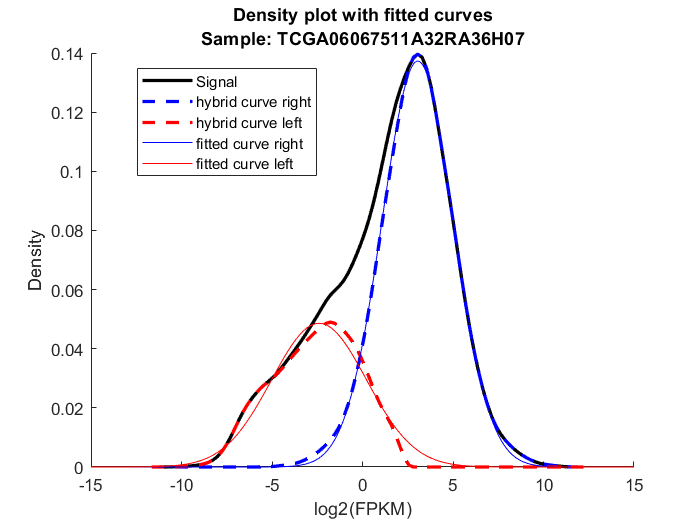

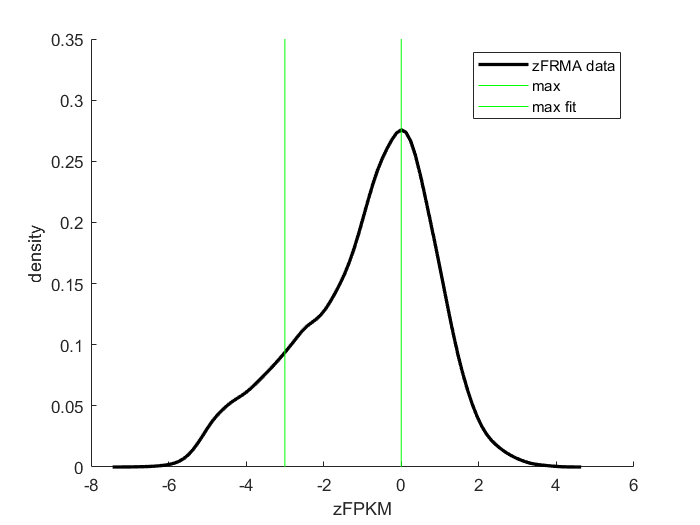

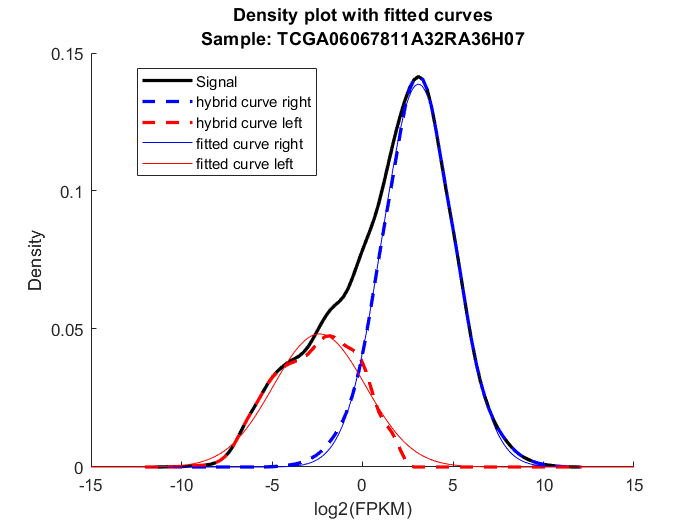

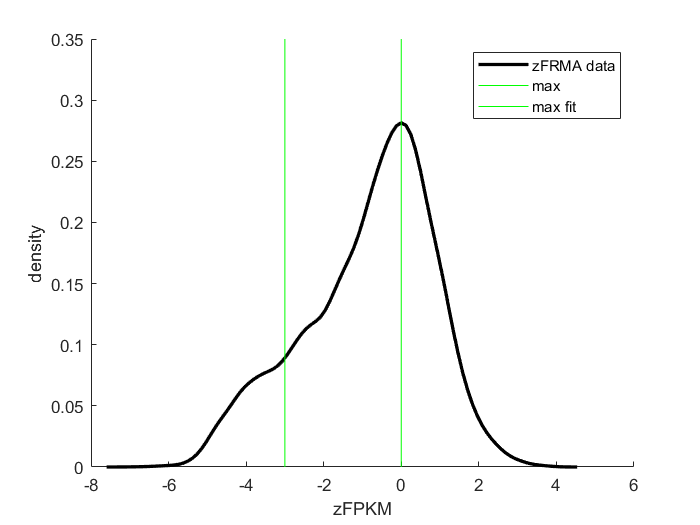

signal = log2(fpkm); % log2-transform the data
signal(isinf(signal)) = -10000; % transform all -Inf to -10000

for j = 1:size(colnames,2) % for each sample
    signal_sample = signal(:,j); % save only current sample
    data_keep = fpkm(:,j);
    signal_sample = signal_sample(signal_sample>-10000); % remove samples with low expression

Density plot

    [probability_estimate,xi] = ksdensity((signal_sample)); % get the densities
    
    if figflag;
        figure; hold on
        plot(xi,probability_estimate,'-k','LineWidth',2);
        title({'Density curve for sample: ', colnames{1,j}});
        ylabel('Density'); xlabel('log2(FPKM)');
        legend({'Signal'},'Location','best');end
    

Create right curve

    peak_max_idx = (find(probability_estimate==max(probability_estimate))); % find the maximum of the density curve
    max_r_side = probability_estimate(peak_max_idx:end); % copy right-most side of density curve
    max_l_side = flip(max_r_side); % mirror the right side
    hybrid = [max_l_side(1:end-1), max_r_side];
    
    hybrid_curve = zeros(numel(probability_estimate),1); % create hybrid curve
    if numel(hybrid)> numel(probability_estimate)
        hybrid_curve(end+1-numel(hybrid(end-100+1:end)):end)=hybrid(end-100+1:end);
        x = zeros(numel(probability_estimate),1); % create new x-axis
    else
        hybrid_curve(end-numel(hybrid)+1:end) = hybrid;
        x = xi;
    end
    
    if figflag
        plot(x,hybrid_curve,'b--','LineWidth',2);
        legend({'Signal','hybrid curve right'});
        title({'Density plot with hybrid curves',['Sample: ', colnames{1,j}]},'interpreter','none');end
    
    clear peak_max_idx max_l_side max_r_side hybrid

Create left curve (main curve - rightmost curve)

    rest_curve = probability_estimate - hybrid_curve';
    rest_curve(find(rest_curve<0.0001))=0;
    
    if figflag;
        plot(xi,rest_curve, 'r--','LineWidth',2);
        legend({'Signal','hybrid curve right','hybrid curve left'});end

## fit the curves

    [fitresult_r, ~] = createFit_r(xi, hybrid_curve); % right curve



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2019
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.22.0).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.


 Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configuring solver environment variables ...
   - [*---] ILOG_CPLEX_PATH: C:\Program Files\ibm\ILOG\CPLEX_Studio129\cplex\matlab\x64_win64
   - [----] GUROBI_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] TOMLAB_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ... Done.
 > Setting default solvers ... Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the d

    [fitresult_l, ~] = createFit_l(xi, rest_curve); % left curve
    
    if figflag;
        plot(fitresult_r,'b');
        plot(fitresult_l),'g';

Elapsed time is 212.304366 seconds.
Elapsed time is 216.232547 seconds.


        title({'Density plot with fitted curves',['Sample: ', colnames{1,j}]},'interpreter','none');
        ylabel('Density'); xlabel('log2(FPKM)');
        legend({'Signal', 'hybrid curve right', 'hybrid curve left','fitted curve right','fitted curve left'});
  %  saveas(gcf,['Figures\density_', colnames{1,j},'.png']);
    end
    

##  zFRMA transform the data and plot the density

    sigma1 = fitresult_r.c1/sqrt(2);
    mu1 = fitresult_r.b1; % x-value of right max
    
    zFRMA = (signal_sample-mu1)/sigma1;
    [yFRMA,xFRMA] = ksdensity(zFRMA);
    
    if figflag; figure;hold on;
        plot(xFRMA,yFRMA,'-k','LineWidth',2);
        xlabel('zFPKM');
        ylabel('density');
        line([0 0], [0.0 0.35],'color', [0,1,0])
        line([-3 -3], [0.0 0.35],'color', [0,1,0]);
        legend({'zFRMA data','max','max fit'});end
    
    clear hybrid_curve probability_estimate rest_curve yFRMA xFRMA x xi ans

## Discretization

    zFRMA = (signal(:,j)-mu1)/sigma1; % calculate zFRMA
    
    sigma2 = fitresult_l.c1/sqrt(2);
    mu2 = fitresult_l.b1; % x-value of left max
    mu2_t=(mu2-mu1)/sigma1;
    
    discretized = zFRMA;
    
    e = 0;
    ue = max(-3, mu2_t);
    zFRMA = reshape(zFRMA,size(data_keep,1),size(data_keep,2));
    
    exp_threshold = e;
    unexp_threshold = ue;
    exp=find(discretized>=exp_threshold);
    not_exp=find(discretized<=unexp_threshold);
    unknown = find(discretized<exp_threshold & discretized>unexp_threshold);
    
    discretized(unknown)    = 0;    % unknown expression is set to 0
    discretized(not_exp)    = -1;   % non-expression is set to -1
    discretized(exp)        = 1;    % expression is set to 1
    
    discretized = (reshape(discretized,size(data_keep,1),size(data_keep,2)));
    discretized_keep(j,:) = discretized'; % save for each sample
    
    clear fitresult_l fitresult_r data_keep e exp exp_threshold mu1 mu2 mu2_t not_exp sigma1 sigma2 signal2 signal_sample ue unexp_threshold unknown zFRMA
end

discretized=discretized_keep';
clear j discretized_keep signal
%close all

# FASTCORMICS

## Prepare FASTCORMICS

needed:

- Cmodel:     a consistent model, here: obtained from running fastcc on Recon204 (from https://vmh.uni.lu/#downloadview)

- dico:   identifier file, which links the geneIDs from the RNA-seq data to the gene identifiers in the model

optional

- **medium**:     defines metabolites in the growth medium of cells to constrain the model, see example medium_example.mat

load cRecon204.mat  % consistent Recon 2.04 model, obtained by running FASTCC (Vlassis et al., 2014)
load medium_example % need to define medium for the cells used here
load dico_ML.mat % dictionary to map the rownname identifier to the genes in the model

Cmodel.genes = regexprep(Cmodel.genes,'\.[0-9]+$',''); %removal of gene transcripts

epsilon = 1e-4;
consensus_proportion = 0.9; %gene has to be expressed in 90% of the cases in order to be included. Only relevant if you want to create one generic model from different samples

Set optional settings such as:

- unpenalizedSystems:      

- func: reaction(s) forced to be present in the model

- not_medium_constrained

- medium : medium composition 

unpenalizedSystems = {'Transport, endoplasmic reticular';
    'Transport, extracellular';
    'Transport, golgi apparatus';
    'Transport, mitochondrial';
    'Transport, peroxisomal';
    'Transport, lysosomal';
    'Transport, nuclear'};
unpenalized = Cmodel.rxns(ismember(Cmodel.subSystems,unpenalizedSystems));
optional_settings.unpenalized = unpenalized;

optional_settings.func = {'DM_atp_c_';'biomass_reaction'}; % forced reactions

not_medium_constrained = 'EX_tag_hs(e)';
optional_settings.not_medium_constrained = not_medium_constrained;

optional_settings.medium = medium_example;% remove field if no constraint is provided

## Create models

the cobra toolbox is needed for the model creation

make sure you have a compatible cplex version for your Matlab version

initCobraToolbox % initialize the COBRA toolbox

single models:

for i = 1:numel(colnames) %for each sample
    [model_out{i}, A_keep{i}] = fastcormics_RNAseq(Cmodel, discretized(:,i), ...
        rownames, dico , 0, consensus_proportion, epsilon, optional_settings);
end

generic models:

[model_out_generic, A_keep_generic] = fastcormics_RNAseq(Cmodel, discretized, ...
    rownames, dico , 0, consensus_proportion, epsilon, optional_settings);